**Amin Chabok - 400126098**

CFD-HW2

FTCS & CTCS 1D heat transfer

Due to the lack of time, a simpler solution of the following equation is considered. After applying the variable change, we get the following equation:


$$\frac{\partial \theta }{\partial t}=\alpha \frac{\partial^2 \theta }{\partial x^2 }-\frac{\textrm{hp}}{A\rho c}\theta$$


This equation is solved by methods FTCS and CTCS, and its various parts, including the domain and boundary conditions, are specified in the code.

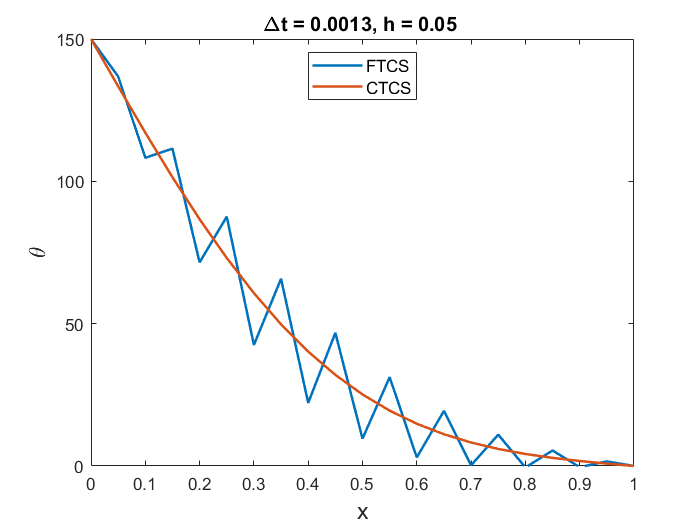

clear all; close all; clc

alpha=1;   % Diffusion Coefficient
L=1;       % Length of Rod
B=0.001;   % hpa/Ak

dx=0.05;   % Position Step
x=0:dx:L;  % Position Intervals
N=L/dx;    % Number of Points in Space

dt=0.0013; % Time Step
T=dt*50;   % Time Interval 
M=T/dt;    % Number of Time Steps

%% Solution of 1D Heat Equation using FTCS
% Initial Conditions (t=0)
u0_f=zeros(length(x),1); % Pre-allocate
for i=1:N+1
    if x(i)<=0.5
        u0_f(i)=2*x(i);
    else
        u0_f(i)=2-2*x(i);
    end
end

% Partial Difference Equation
u1_f=u0_f; % Pre-allocate
for j=1:M % Time Iterations
    for i=2:N % Position Iterations
        u1_f(i)=(1-B)*u0_f(i)+(alpha*dt/dx^2)*(u0_f(i+1)-2*u0_f(i)+u0_f(i-1));
    end
    % Boundary Conditions (x=0, x=L)
    u1_f(1)=150;
    u1_f(N+1)=0;
    u0_f=u1_f; % Update BCs
end

%% Solution of the Heat Equation Using CTCS

% Coefficients of the tridiagonal system
b = (-alpha/dx^2); % Super diagonal: coefficients of u(i+1)
c = b;             % Subdiagonal: coefficients of u(i-1)
a = (1/dt)-(b+c);  % Main Diagonal: coefficients of u(i)

% Tridiagonal matrix
A = diag(a*ones(1,N+1))+diag(b*ones(1,N),1)+diag(c*ones(1,N),-1);
% Fix coefficients of boundary nodes
A(1,1)=1; A(1,2)=0; A(end,end)=1; A(end,end-1)=0;

% Initial Conditions
u1_b=zeros(length(x),1);
for i=1:N+1
    if x(i)<=0.5
        u1_b(i)=2*x(i);
    else
        u1_b(i)=2-2*x(i);
    end
end
% Boundary Conditions
ub=[150, 0];

% Loop over time steps
for i = 1:M
    d = [ub(1); u1_b(2:N)/dt; ub(2)]; % Update LHS and preserve BCs
    u1_b = A\d; % Solve the system
end

%% Plot Solutions
figure()
plot(x,u1_f,x,u1_b,'LineWidth',1.5)
title(['\Deltat = ',num2str(dt),', ','h = 0.05 '],'FontSize',12)
xlabel('x','FontSize',14),xlim([0,1])
ylabel('\theta','FontSize',14),ylim([0,150])
legend('FTCS','CTCS', 'FontSize',10,'Location','North')